## Introduction to battery modelling with BATTMO - part 2

Electrochemical system: Thermodynamics, Kinetics,Transport

DFN model parts:

Model equations for transport in porous electrode -Fick's law, electron transport-ohm's law, charge transport at interface:butler volmer eqn, mass transport in electrolyte:concentrated solution theory.

Overpotential figure:

vary the parameters for thermodynamics at slow C rate c/20: maximum Li ion concentration,active materials

vary the transport parameters at high c rate: Diffusion coeffiecient,particle radius of electrode materials

vary the kinetic parameters-rate constant,exchange current density,activation energy,charge transfer coefficients

input_parameter_1="NegativeElectrode.Coating.ActiveMaterial.electronicConductivity";
input_parameter_2="Control.CRate";
parameter_array_1=[100,200,900];
parameter_array_2=[2,3,4]

parameter_array_2 =      2     3     4


Crate=1;
input_parameter_1="NegativeElectrode.Coating.ActiveMaterial.electronicConductivity";

input_parameter_5="NegativeElectrode.Coating.ActiveMaterial.electronicConductivity";
C = split(input_parameter_5,'.');
jsonstruct_8 = parseBattmoJson('Examples/JsonDataFiles/sample_input.json');
jsonstruct_8 = setfield(jsonstruct_8,C{:},1026)

jsonstruct_8 = struct with fields:
                   use_thermal: 0
    include_current_collectors: 0
                      Geometry: [1×1 struct]
             NegativeElectrode: [1×1 struct]
             PositiveElectrode: [1×1 struct]
                     Separator: [1×1 struct]
                       Control: [1×1 struct]
                   Electrolyte: [1×1 struct]
                  ThermalModel: [1×1 struct]
                  TimeStepping: [1×1 struct]
                        Output: [1×1 struct]
                           SOC: 0.9900
                         initT: 298.1500


jsonstruct_8.NegativeElectrode.Coating.ActiveMaterial.electronicConductivity

ans = 1026

   100

Solving timestep 01/45:              -> 1 Second, 546 Milliseconds
Solving timestep 02/45: 1 Second, 546 Milliseconds -> 3 Seconds, 93 Milliseconds
Solving timestep 03/45: 3 Seconds, 93 Milliseconds -> 6 Seconds, 187 Milliseconds
Solving timestep 04/45: 6 Seconds, 187 Milliseconds -> 12 Seconds, 375 Milliseconds
Solving timestep 05/45: 12 Seconds, 375 Milliseconds -> 24 Seconds, 750 Milliseconds
Solving timestep 06/45: 24 Seconds, 750 Milliseconds -> 49 Seconds, 500 Milliseconds
Solving timestep 07/45: 49 Seconds, 500 Milliseconds -> 99 Seconds
Solving timestep 08/45: 99 Seconds   -> 148 Seconds, 500 Milliseconds
Solving timestep 09/45: 148 Seconds, 500 Milliseconds -> 198 Seconds
Solving timestep 10/45: 198 Seconds  -> 247 Seconds, 500 Milliseconds
Solving timestep 11/45: 247 Seconds, 500 Milliseconds -> 297 Seconds
Solving timestep 12/45: 297 Seconds  -> 346 Seconds, 500 Milliseconds
Solving timestep 13/45: 346 Seconds, 500 Milliseconds -> 396 Seconds
Solving timestep 14/45: 

*** Simulation complete. Solved 45 control steps in 2 Seconds, 481 Milliseconds ***
   100

Solving timestep 01/45:             -> 773 Milliseconds
Solving timestep 02/45: 773 Milliseconds -> 1 Second, 546 Milliseconds
Solving timestep 03/45: 1 Second, 546 Milliseconds -> 3 Seconds, 93 Milliseconds
Solving timestep 04/45: 3 Seconds, 93 Milliseconds -> 6 Seconds, 187 Milliseconds
Solving timestep 05/45: 6 Seconds, 187 Milliseconds -> 12 Seconds, 375 Milliseconds
Solving timestep 06/45: 12 Seconds, 375 Milliseconds -> 24 Seconds, 750 Milliseconds
Solving timestep 07/45: 24 Seconds, 750 Milliseconds -> 49 Seconds, 500 Milliseconds
Solving timestep 08/45: 49 Seconds, 500 Milliseconds -> 74 Seconds, 250 Milliseconds
Solving timestep 09/45: 74 Seconds, 250 Milliseconds -> 99 Seconds
Solving timestep 10/45: 99 Seconds  -> 123 Seconds, 750 Milliseconds
Solving timestep 11/45: 123 Seconds, 750 Milliseconds -> 148 Seconds, 500 Milliseconds
Solving timestep 12/45: 148 Seconds, 500 Milliseconds ->

*** Simulation complete. Solved 45 control steps in 2 Seconds, 558 Milliseconds ***


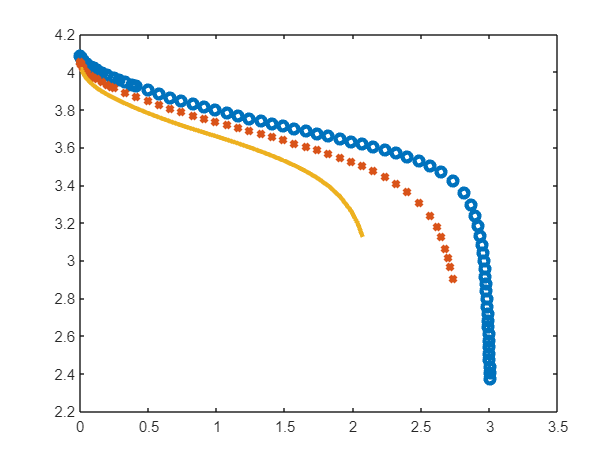

plot_capacities(parameter_array_2,input_parameter_2,Crate)

function plot_capacities(parameterArray,input_parameter, CRate)
    % Function to take in the specific input parameter along with its
    % values and c-rate and plot the capacities
    %
    % Parameters:
    % parameterArray - a numeric vector
    % input_parameter - a string specifying the operation ('sum', 'mean', 'scale')
    % crate - a numeric value used for scaling (only for 'scale' operation)
    %
    % Returns:
    % None
    % instantiate an empty figure
    figure()
    jsonstruct = parseBattmoJson('Examples/JsonDataFiles/sample_input.json'); % load default input
    output = cell(size(parameterArray));
    markers={'o',"x",'-'};
    for i = 1:numel(parameterArray)
        jsonstruct.Control.CRate = CRate;
        C = split(input_parameter,'.');
        jsonstruct = setfield(jsonstruct,C{:},parameterArray(i));
        disp(jsonstruct.NegativeElectrode.Coating.ActiveMaterial.electronicConductivity);    
        jsonstruct.TimeStepping.totalTime = (1./jsonstruct.Control.CRate) .* 3600 .* 1.1;
        % run the simulation and store the results in the output cell array
        output{i} = runBatteryJson(jsonstruct);
         % retrieve the states from the simulation result
        states = output{i}.states;
        % extract the time and voltage quantities
        time = cellfun(@(state) state.time, states);
        voltage = cellfun(@(state) state.('Control').E, states);
        current = cellfun(@(state) state.('Control').I, states);
        % calculate the capacity
        capacity = time .* current;
        % plot capacity vs voltage
        plot((capacity/(hour*milli)), voltage, markers{i}, 'linewidth', 3);
        hold on
    end    
end